clearvars
close all
clc

# Model Based Regulator Design of Cart Pole System

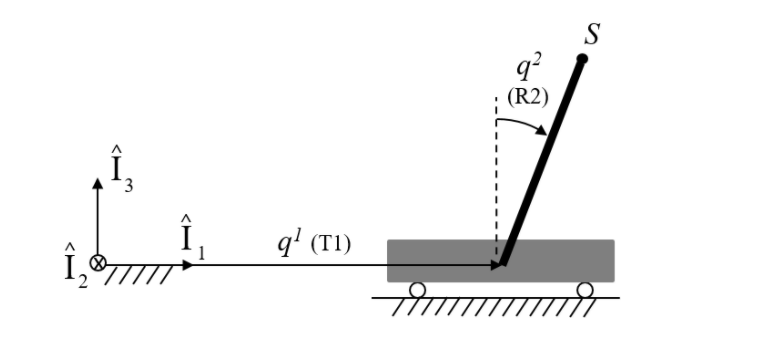

## System Description

The cart translates with respect to the inertial frame in one dimension freely and no external force is applied on the cart. The cart is assumed to be a simple lumped mass block. The pole is a uniformly distributed stick with its centre of mass at its geometric centre. It rotates with respect to the translating cart with the help of a revolute joint. The system is a lumped parameter system which can be represented by ordinary differential equations.

## System Parameters:

#### 
$$m_{Cart} = 10 kg$$


#### 
$$m_{Pole} = 2 kg$$


#### 
$$l_{Pole} = 4 m$$


% Cart mass
M = 10;%kg

% Pole mass
m = 2;%kg

% Pole length
L = 4;%meters

% Acceleration due to gravity
g = 9.81; %m/s^2

% Time Step Size
dt = 0.01;

% Time Vector
t_span = [0:dt:10];


### State vector of system:

### 
$$\;\mathbf{w}=\;\left\lbrack \begin{array}{c}
x\\
\theta \\
\dot{x} \\
\theta^˙ 
\end{array}\right\rbrack$$


### First Derivative of states:

### 
$$\dot{\mathbf{w}} =\left\lbrack \begin{array}{c}
\dot{x} \\
\theta^˙ \\
\ddot{x} \\
\theta^¨ 
\end{array}\right\rbrack$$


### Initial conditions of the system:

The cart is assumed to be at 0.1 m to the right (positive X axis) initially, with all the other states at zero.

w_0 = [0;0.5;0;0];

# Dynamics of Actuated Cart Pole System:

#### Euler-Lagrange Equation of the system:

### $\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}}\right) - \frac{\partial L}{\partial q} = Q(t)$, for an actuated/forced system

## Linear State space representation of the system:

The equations of motion of the cart pendulum system can be written as:

## Case 1: Actuation provided to Cart and Pole Joint

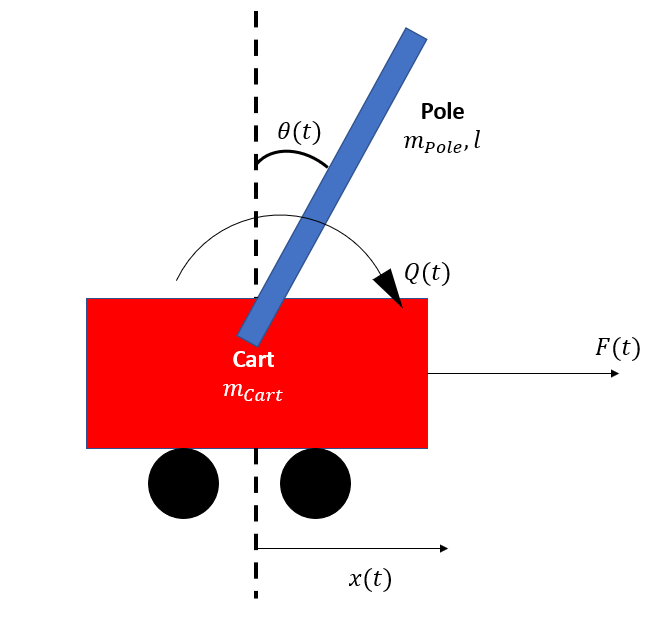

#### Linearized Equation of Motion (assuming small pole joint rotations):

### 
$$(m_{Cart} + m_{Pole})\ddot{x}_{Cart} + \frac{m_{Pole}l_{Pole}}{2}\ddot{\theta} = f(t)$$


### 
$$\frac{m_{Pole}l_{Pole}^{2}}{3}\ddot{\theta} + \frac{m_{Pole}l_{Pole}}{2}\ddot{x}_{Cart} - \frac{m_{Pole}gl_{Pole}}{2}\theta = Q(t)$$


### 
$$\dot{\textbf{w}} = \textbf{A}\cdot\textbf{w} + \textbf{B}\cdot\textbf{u}$$


### where,

### $\mathbf{A}=\left\lbrack \begin{array}{cc}
\mathbf{O} & \mathbf{I}\\
{-\mathbf{M}}^{-1} \mathbf{K} & \mathbf{O}
\end{array}\right\rbrack$, system matrix / State Weighing Matrix

### $\mathbf{B}=\left\lbrack \begin{array}{c}
\mathbf{O}\\
{\mathbf{M}}^{-1} 
\end{array}\right\rbrack$, Control Cost Matrix

### $\mathbf{M}=\left\lbrack \begin{array}{cc}
m_{\mathit{Cart}} +m_{\mathit{Pole}}  & \frac{m_{\mathit{Pole}} l_{\mathit{Pole}} }{2}\\
\frac{m_{\mathit{Pole}} l_{\mathit{Pole}} }{2} & \frac{m_{\mathit{Pole}} {l_{\mathit{Pole}} }^2 }{3}
\end{array}\right\rbrack$, **mass matrix**

### $\mathbf{K}=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & -\frac{m_{\mathit{Pole}} gl_{\mathit{Pole}} }{2}
\end{array}\right\rbrack$, **stiffness matrix**

## Case 2: Actuation provided to Cart only

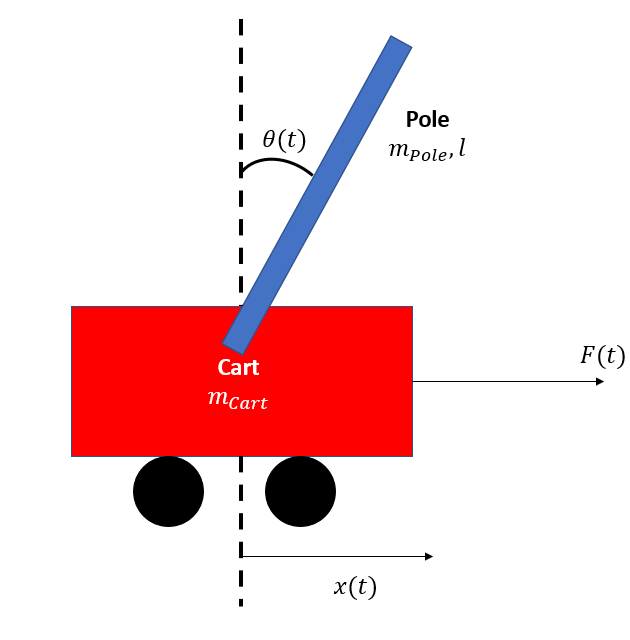

#### Linearized Equation of Motion (assuming small pole joint rotations):

### 
$$(m_{Cart} + m_{Pole})\ddot{x}_{Cart} + \frac{m_{Pole}l_{Pole}}{2}\ddot{\theta} = f(t)$$


### 
$$\frac{m_{Pole}l_{Pole}^{2}}{3}\ddot{\theta} + \frac{m_{Pole}l_{Pole}}{2}\ddot{x}_{Cart} - \frac{m_{Pole}gl_{Pole}}{2}\theta = 0$$


### 
$$\mathbf{B}=\left\lbrack \begin{array}{c}
0\\
0\\
\frac{4}{4m_{\mathit{Cart}} +m_{\mathit{Pole}} }\\
-\frac{6}{4m_{\mathit{Cart}} l+m_{\mathit{Pole}} l}
\end{array}\right\rbrack$$


### 
$$\mathbf{D}=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \;$$


### 
$$\mathbf{u}=f\left(t\right)$$


% Variable for determing actuation
act = 'Both';

if strcmp(act,'Both')
    fprintf('Both Cart and Pole Joint are actuated')
elseif strcmp(act,'Cart')
    fprintf('Horizontal Actuating Force provided to Cart')
elseif strcmp(act,'Pole')
    fprintf('Rotational Actuating Torque provided at Pole Joint')
end

Both Cart and Pole Joint are actuated

% Mass Matrix
M_mat = [m + M,(m*L)/2;
    (m*L)/2,(m*(L)^2)/3];
% Stiffness Matrix
K_mat = [0,0;
    0,(-m*g*L)/2];
% State Weighing matrix
A = [zeros(2,2),eye(2,2);-M_mat\K_mat,zeros(2,2)];
% Controller Cost matrix
switch act
    case 'Both'
        B = [zeros(size(M_mat)) ; M_mat\eye(size(M_mat))];
        D = zeros(2,2);
        
    case 'Pole'
        B = [0;0;(-6)/(L*(4*M + m));(12*(M + m))/((m*(L^2))*(4*M + m))];
        D = zeros(2,1);
        
    case 'Cart'
        B = [0;0;(4)/(4*M + m);(-6)/(4*M*L + m*L)];
        D = zeros(2,1);
end


## **Controller Gains**

% Vartiable defining the controller used
controller = 'PD';

**If a general controller is used which only takes the horizontal position of the cart and the angular position of the pole as feedback**

% Controller Gain Matrix
Kc = [100,100;
    100,100];

**If a PD Controller is used which takes the positions and velocities of both the cart and the pole as feedback**

% Proportional Gain Matrix
Kp = [10,50;
     -50,20];
% Derivative Gain Matrix
Kd = [50,10;
    -10,50];

## Response of the Closed Loop Model Based Control System:

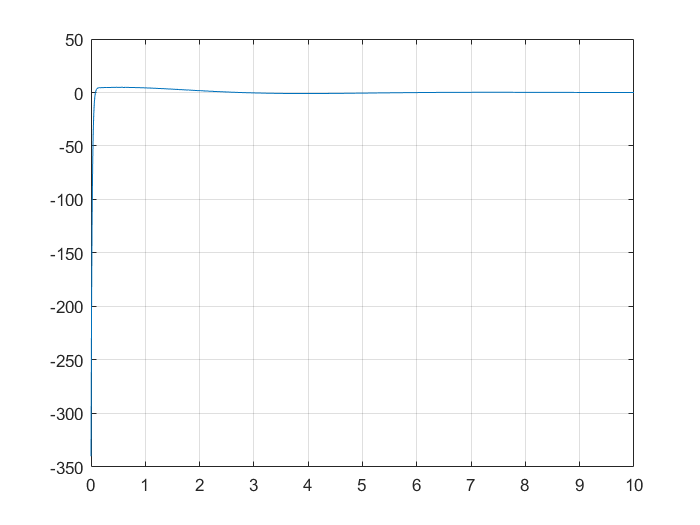

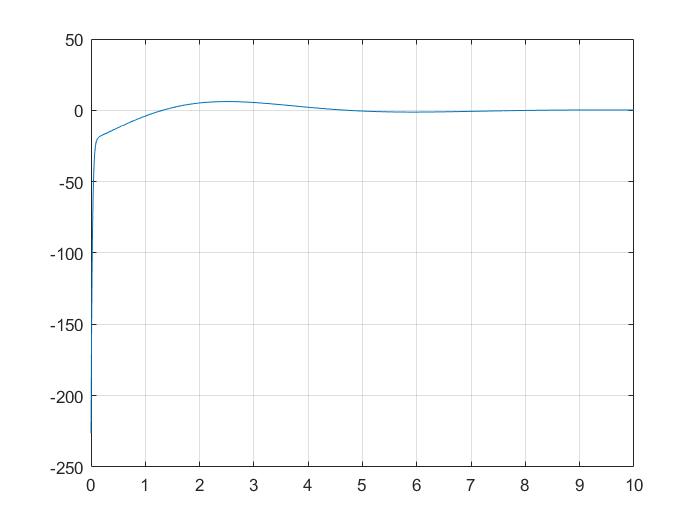

switch controller
    case 'General'
        % Closed Loop Dynamics
        [t,w] = ode45(@(t,w)ModelBasedControl_SSR(t,w,M_mat,K_mat,Kc,Kp,Kd,A,B,controller),t_span,w_0);
        % Closed Loop System Weighing Matrix
        A_cl = A + [B*(K_mat - M_mat*Kc), zeros(4,2)];
        % Controller/Actuator Effort
        for i = 1:max(size(w))
            u(:,i) = -M_mat*Kc*[w(i,1);w(i,2)] + K_mat*[w(i,1);w(i,2)];
            uCart(i) = u(1,i);
            uPole(i) = u(2,i);
        end
        
    case 'PD'
        % Closed Loop Dynamics
        [t,w] = ode45(@(t,w)ModelBasedControl_SSR(t,w,M_mat,K_mat,Kc,Kp,Kd,A,B,controller,act),t_span,w_0);
        % Closed Loop System Weighing Matrix
        switch act
            case 'Cart'
                A_cl = A + [B*[1,0]*(K_mat - M_mat*Kp), -B*[1,0]*M_mat*Kd];
                % Controller/Actuator Effort
                for i = 1:max(size(w))
                    u1 = -M_mat*Kd*[w(i,3);w(i,4)] + (K_mat - M_mat*Kp)*[w(i,1);w(i,2)];
                    u(:,i) = [1,0]*u1;
                end
                
                % Plotting Actuator Effort
                figure
                plot(t_span,u)
                grid on
                
            case 'Pole'
                A_cl = A + [B*[0,1]*(K_mat - M_mat*Kp), -B*[0,1]*M_mat*Kd];
                % Controller/Actuator Effort
                for i = 1:max(size(w))
                    u1 = -M_mat*Kd*[w(i,3);w(i,4)] + (K_mat - M_mat*Kp)*[w(i,1);w(i,2)];
                    u(:,i) = [0,1]*u1;
                end
                
                % Plotting Actuator Effort
                figure
                plot(t_span,u)
                grid on
               
            case 'Both'
                A_cl = A + [B*(K_mat - M_mat*Kp), -B*M_mat*Kd];
                % Controller/Actuator Effort
                for i = 1:max(size(w))
                    u(:,i) = -M_mat*Kd*[w(i,3);w(i,4)] + (K_mat - M_mat*Kp)*[w(i,1);w(i,2)];
                    uCart(i) = u(1,i);
                    uPole(i) = u(2,i);
                end
                
                figure
                plot(t_span,uCart)
                grid on
                
                figure
                plot(t_span,uPole)
                grid on
        end
end


% Closed Loop Eigen-values
ClosedLoopPoles = eig(A_cl)

ClosedLoopPoles =  -49.5278 + 9.0765i
 -49.5278 - 9.0765i
  -0.4722 + 0.9176i
  -0.4722 - 0.9176i


There are controller gain matrices for which the closed loop system is stable

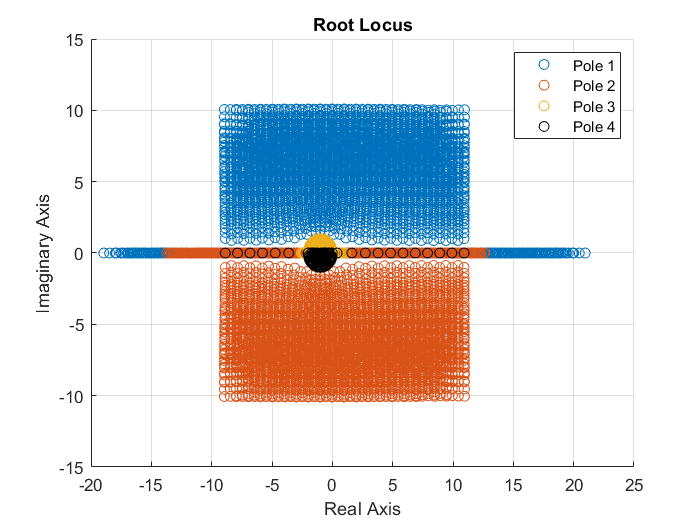


% Variation of location of closed loop system poles for varying controller
% parameters (root locus)

% Varying controller gains
% Number of variations for each design parameter (controller gain element)
num_ContGain = 10;
% Proportial Gain
count = 1;
for Kp1 = -num_ContGain:num_ContGain
    for Kp2 = -num_ContGain:num_ContGain
        for Kp3 = -num_ContGain:num_ContGain
            for Kp4 = -num_ContGain:num_ContGain
                Kp_var(:,:,count) = [Kp1,Kp2;Kp3,Kp4];
                count = count + 1;
            end
        end
    end
end

% Derivative Gain
count = 1;
for Kd1 = -num_ContGain:num_ContGain
    for Kd2 = -num_ContGain:num_ContGain
        for Kd3 = -num_ContGain:num_ContGain
            for Kd4 = -num_ContGain:num_ContGain
                Kd_var(:,:,count) = [Kd1,Kd2;Kd3,Kd4];
                count = count + 1;
            end
        end
    end
end

% Root Locus of the closed loop poles for the given controller gains
ClosedLoopRootLocus(A,B,K_mat,M_mat,Kp_var,Kd_var,act)

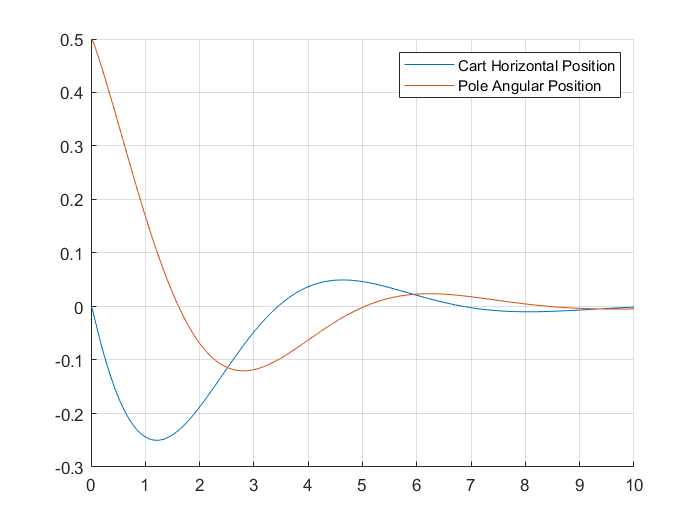


% Response of the Closed Loop Control System
figure
hold on
plot(t_span,w(:,1))
plot(t_span,w(:,2))
legend('Cart Horizontal Position','Pole Angular Position')
grid on